**Color-based segmentation ** 

Display the 6 images in grayscale and split them in the three RGB channels and in

the three HSV channels.  

Carico le immagini in rgb

img1 = imread("ur_c_s_03a_01_L_0376.png");
img2 = imread("ur_c_s_03a_01_L_0377.png");
img3 = imread("ur_c_s_03a_01_L_0378.png");
img4 = imread("ur_c_s_03a_01_L_0379.png");
img5 = imread("ur_c_s_03a_01_L_0380.png");
img6 = imread("ur_c_s_03a_01_L_0381.png");

Grafico le immagini in rgb nei tre componenti e in hsv:

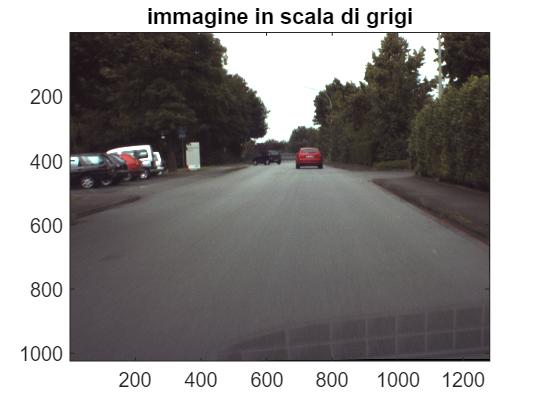

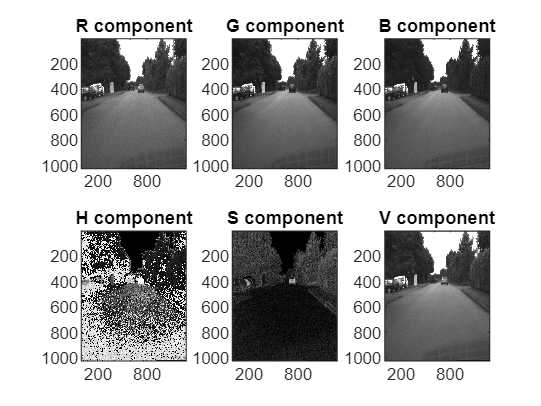

[img_hsv1] = rgbToHsv(img1);

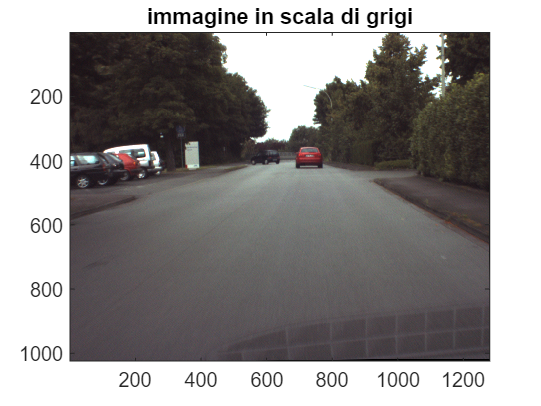

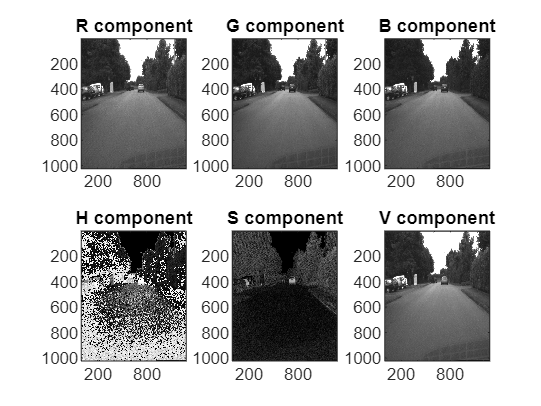

[img_hsv2] = rgbToHsv(img2);

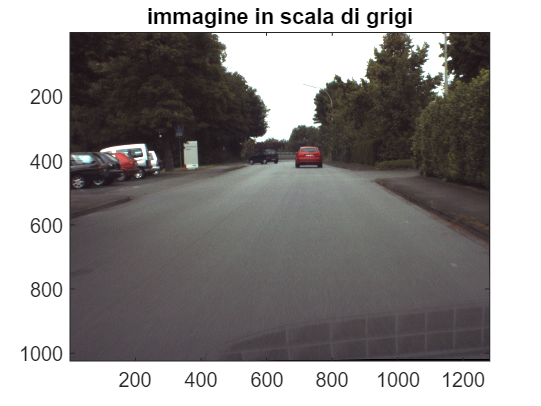

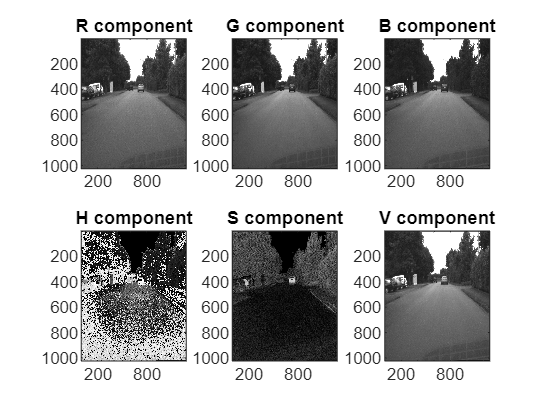

[img_hsv3] = rgbToHsv(img3);

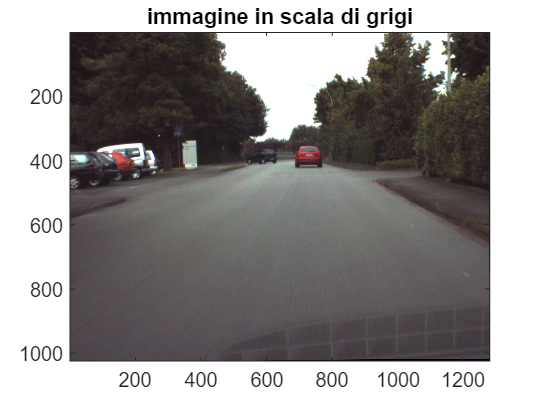

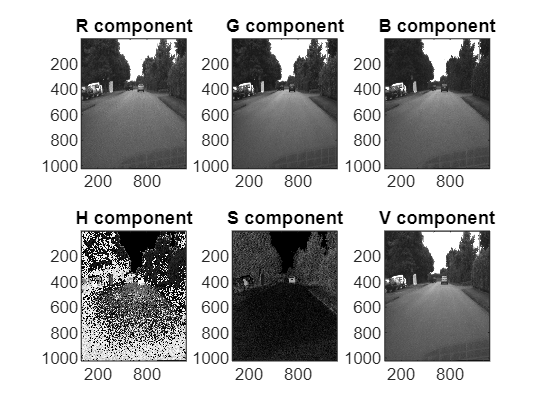

[img_hsv4] = rgbToHsv(img4);

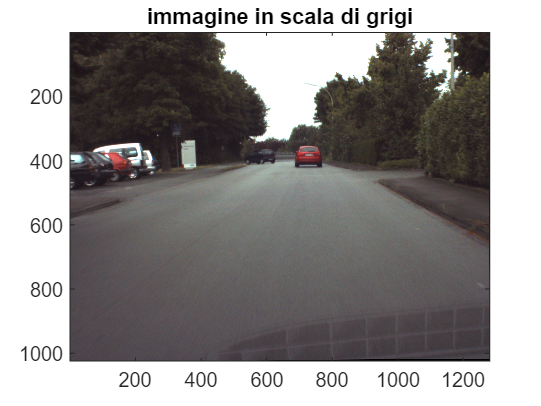

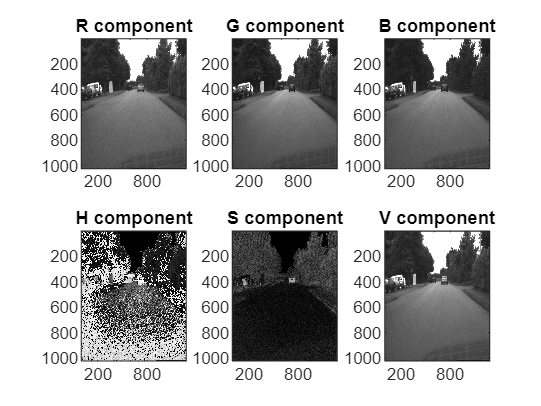

[img_hsv5] = rgbToHsv(img5);

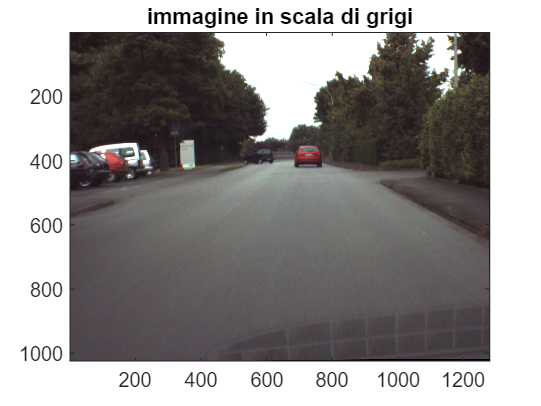

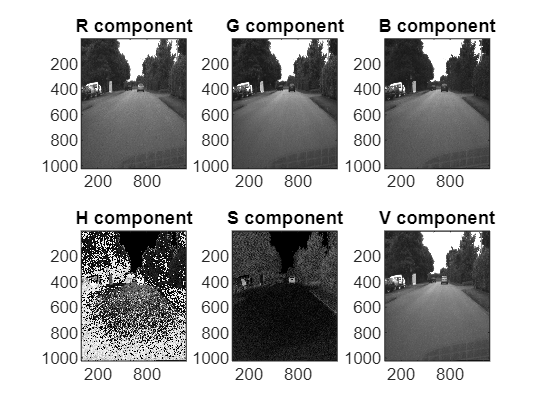

[img_hsv6] = rgbToHsv(img6);

Note the variation of the RGB components and of the Hue one in the area of the dark car that turns on the left for the 6 images.  

Select in the image “ur_c_s_03a_01_L_0376.png” the area corresponding to the dark car that turns on the left, e.g. area [390:400,575:595]. In this area compute the mean value (*m*) and the standard deviation (*s*) of the Hue component.  

img_black_car1 = img_hsv1(390:400,575:595,1);
img_black_car2 = img_hsv1(360:420,550:650,1);

ma = zeros(2,1);
sa = m;
seg = m;
ma(1,1) = mean(img_black_car1,"all");
sa(1,1) = std2(img_black_car1);
ma(2,1) = mean(img_black_car2,"all");
sa(2,1) = std2(img_black_car2);


Viene estratta la componente H (tonalità) dall'immagine in formato HSV (`img_hsv1`). Questo può essere utile per rilevare oggetti con determinate tonalità.

Una regione di interesse (`AHarea`) viene estratta dalla componente H dell'immagine. Questa regione sembra essere una piccola porzione dell'immagine, definita da una finestra 10x20 di pixel, con angolo in alto a sinistra in (390, 575) e angolo in basso a destra in (400, 595).

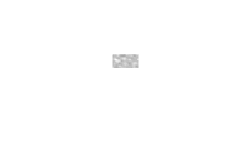

areaH = img_hsv1(:,:,1);
AHarea = areaH(390:400,575:595);
%figure, imshow(AHarea), colormap gray;

Viene calcolata la media (`m`) e la deviazione standard (`s`) dei valori di pixel all'interno di `AHarea`

m = mean2(AHarea);
s = std2(AHarea);
"The mean is: "+ m

ans = "The mean is: 0.77408"

"The standard deviation is: " + s

ans = "The standard deviation is: 0.052077"

Black car

Viene applicato un criterio per identificare i pixel dell'immagine originale (`img_hsv1`) che corrispondono a valori di tonalità (`H`) vicini alla media `m` entro una soglia definita dalla deviazione standard `s`. Questo risultato viene salvato in `THimg`, che rappresenta una maschera binaria.

%setting variables
threshold = s;
%uncomment for red car
%m = 0.985;
%s = 0.015;


Himg = img_hsv1(:,:,1);
THimg = (Himg > (m - threshold)) & (Himg < (m + threshold));

Viene creata una matrice vuota (`base`) con le stesse dimensioni dell'immagine originale, e la maschera `THimg` viene sommata a `base` per evidenziare l'area corrispondente alla soglia di tonalità specificata.

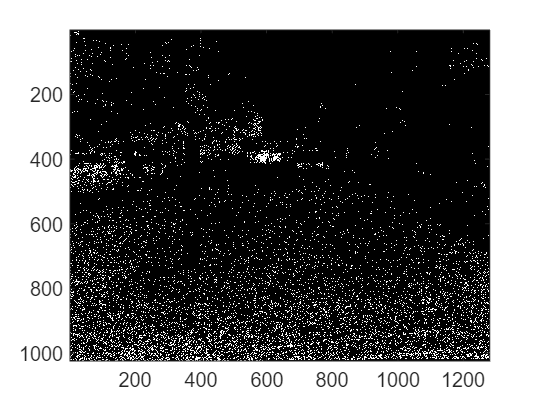

base = zeros(1024, 1280);
res = base + THimg;
figure, imagesc(res), colormap gray

Centroid

Viene utilizzata la funzione `regionprops` per analizzare la maschera `THimg` e trovare proprietà delle regioni connessi, come l'area, il centroide e i limiti dell'area. In questo caso, sembra essere interessata solo all'area della regione più grande.

prop=regionprops(THimg,'Area','Centroid','BoundingBox');
[m, i] = max([prop.Area]);
xc=floor(prop(i).Centroid(1));
yc=floor(prop(i).Centroid(2));
ul_corner_width=prop(i).BoundingBox;

Il codice estrae le informazioni sulla regione più grande (presumibilmente rappresentante l'oggetto rilevato) e traccia il centroide di questa regione sull'immagine originale. Viene anche disegnato un rettangolo attorno all'area dell'oggetto rilevato.

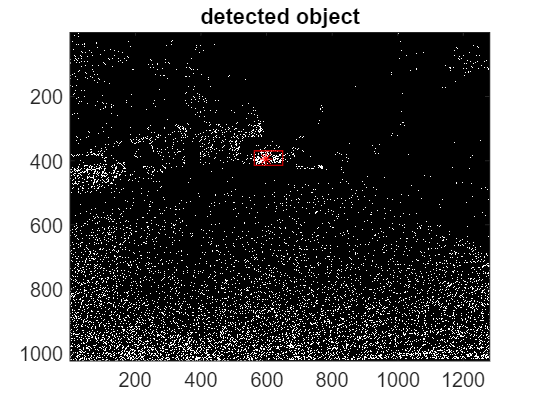

figure,imagesc(res),colormap gray,title('detected object')
hold on
plot(xc,yc,'*r')
rectangle('Position',ul_corner_width,'EdgeColor',[1,0,0])

In generale, sembra che il codice sia progettato per rilevare un oggetto con una tonalità specifica nell'immagine HSV e quindi individuarne la posizione e le dimensioni. Le soglie (`m` e `threshold`) possono essere regolate per modificare la sensibilità del rilevamento in base ai dati dell'immagine specifica.

Segment the dark car in the 6 images by thresholding the Hue component (e.g. in the range between *m-s *and *m+s*)  

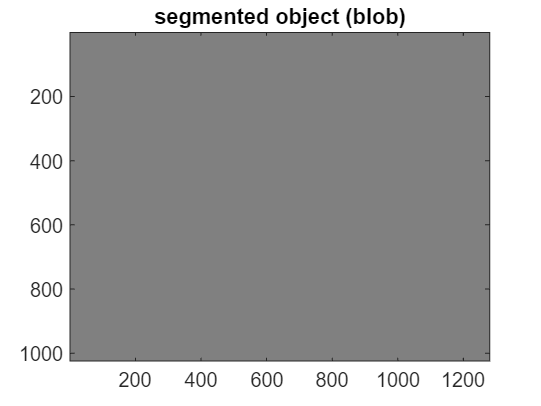

Index in position 1 exceeds array bounds. Index must not exceed 1.

%Seg dovrei avere due valori
for ind = 1:2
    [seg1] = SegmentDark(img_hsv1,m(ind,1),s(ind,1));
end

Display (i) the binary images corresponding to the segmentation and the related centroid and bounding box; (ii) the centroid and bounding box overlapped on the color image (tips: *regionprops() *function needs a logical matrix; display the bounding box of the blob with the highest area; see Fig.1)

for ind = 1:2
    displayblob(seg1);
end

Tutte le funzionii utilizzate per il codice

function [img_hsv] = rgbToHsv (img_rgb)
    img_hsv=rgb2hsv(img_rgb);
    figure,imagesc(img_rgb),colormap gray,title('immagine in scala di grigi')
    figure,subplot(236)
    subplot(231),imagesc(img_rgb(:,:,1)),colormap gray,title('R component')%as intensity
    subplot(232),imagesc(img_rgb(:,:,2)),colormap gray,title('G component')%as intensity
    subplot(233),imagesc(img_rgb(:,:,3)),colormap gray,title('B component')%as intensity
    subplot(234),imagesc(img_hsv(:,:,1)),colormap gray,title('H component')%as intensity
    subplot(235),imagesc(img_hsv(:,:,2)),colormap gray,title('S component')%as intensity
    subplot(236),imagesc(img_hsv(:,:,3)),colormap gray,title('V component')%as intensity
end



function [seg] = SegmentDark (img_hsv,m,s)
    [rr,cc,pp]=size(img_hsv);
    seg=zeros(rr,cc);
    mask=img_hsv(:,:,1)>(m-s) & img_hsv(:,:,1)<m+s; %threshold on the hue componet
    seg=seg+mask;
    figure,imagesc(seg),colormap gray, title('segmented object (blob)') %binary image (segmented image, i.e. detection of a given color)
end

function displayblob (seg)
    %%%Properties of image regions  (blob analysis)
    %binary image seg has only one detected object, the white area (blob), thus
    %we can consider the seg image as labeled one, i.e. the unique blob has
    %label 1
    prop=regionprops(seg, 'Area','Centroid','BoundingBox');
    xc=floor(prop(1).Centroid(1));
    yc=floor(prop(1).Centroid(2));
    ul_corner_width=prop(1).BoundingBox;
    figure,imagesc(seg),colormap gray,title('detected object')
    hold on
    plot(xc,yc,'*r')
    rectangle('Position',ul_corner_width,'EdgeColor',[1,0,0])
end